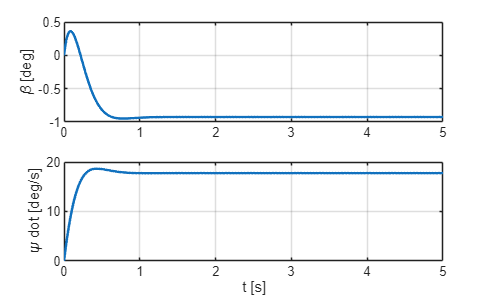

%% Parameter und deren Einheiten
m  = 2000;% kg
J  = 4000;% kgm²
lv = 1.43;% m
lh = 1.4;% m
cv = 70000;% N/rad
ch = 140000;% N/rad
v  = 18;% m/s

delta = 5*pi/180;    % Sprung in rad

%% Zustandsraummatrix
A = [-(cv+ch)/(m*v),  (ch*lh - cv*lv)/(m*v^2) - 1;
     (ch*lh - cv*lv)/J, -(cv*lv^2 + ch*lh^2)/(J*v)];

B = [cv/(m*v);
     cv*lv/J];

C = eye(2);
D = [0;0];

sys = ss(A,B,C,D);

%% Simulation
t = 0:0.01:5;
u = delta*ones(size(t));

[y,t,x] = lsim(sys,u,t);

beta = y(:,1);       % rad
psi_dot = y(:,2);    % rad/s

%% Umrechnung in Grad
beta_deg = beta*180/pi;
psi_dot_deg = psi_dot*180/pi;

%% Plot
figure
subplot(2,1,1)
plot(t,beta_deg,'LineWidth',1.5)
grid on
ylabel('\beta [deg]')

subplot(2,1,2)
plot(t,psi_dot_deg,'LineWidth',1.5)
grid on
ylabel('\psi dot [deg/s]')
xlabel('t [s]')